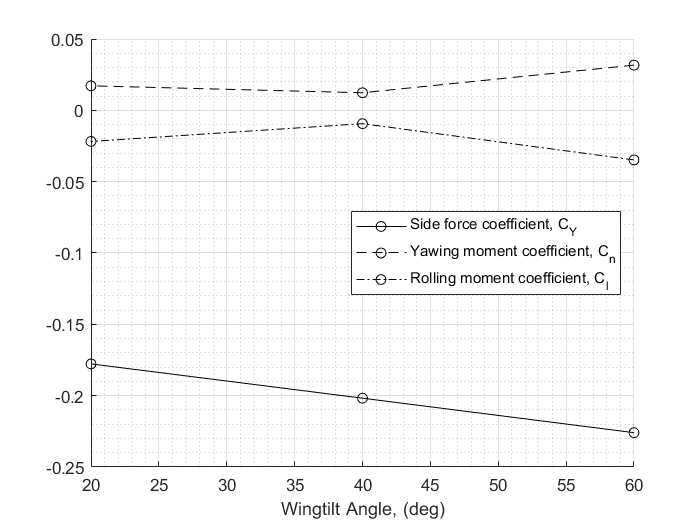

clear all; clc

% Data settings
Speed = [5, 75, 10];
tilt = [60, 40, 20];

% Aircraft Geometry
S = 0.03469846; %m^2 (1578 ft^2/65^2)
b = 0.55332923; %m (118 ft/65)

% Atmospheric Conditions
rho = 1.21; %kg/m^3

for i = 1:length(Speed)

    % Get file names
    fileName = "u_"+ string(Speed(i)) + "_a0_b5_r8_t" + string(tilt(i)) +".mat";
        
    x = load (fileName);
    
    % Get CY, Cn, Cl
    CY(i) = -(x.Fy) / (0.5*rho*x.V^2*S);
    Cn(i) = (x.Tz) / (0.5*rho*x.V^2*S*b);
    Cl(i) = (x.Tx) / (0.5*rho*x.V^2*S*b);
    
    clear x fileName;
end

% Side force, Yaw moment, Rolling moment vs. Sideslip angle for 5 deg
% sideslip

figure

hold on
plot(tilt, CY,'-ok')
plot(tilt, Cn,'--ok')
plot(tilt, Cl,'-.ok')
hold off

xlabel('Wingtilt Angle, (deg)')
grid on 
grid minor

legend('Side force coefficient, C_{Y}', 'Yawing moment coefficient, C_{n}', 'Rolling moment coefficient, C_{l}','Location','east')